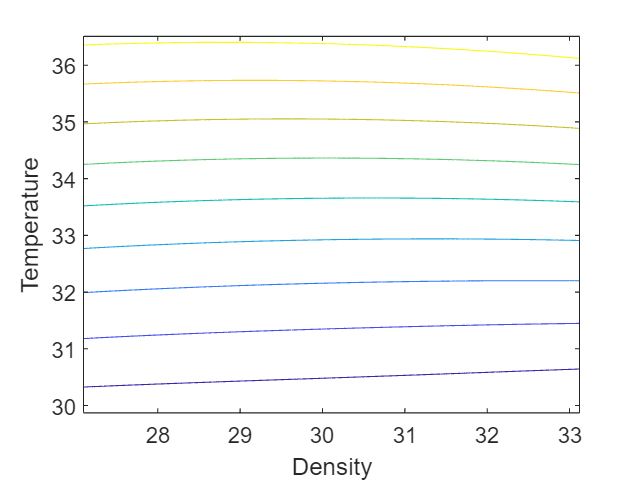

%isotherms on dP vs rho
%isotherms on dP2 vs rho

ispecies = nH2;
Tlist = (0.9:0.002:1.1)*Tcrit_i(ispecies);
rlist = (0.9:0.002:1.1)*rcrit_i(ispecies);

p = zeros(length(Tlist),length(rlist));
dpdr_r = zeros(length(Tlist),length(rlist));
d2pdr2_r = zeros(length(Tlist),length(rlist));

for i = 1:length(Tlist)
    T = Tlist(i);
    for j = 1:length(rlist)
        rho = rlist(j);
        p(i,j) = P_irT(ispecies,rho,T);
        dpdr_r(i,j) = dPdr_irT(ispecies,rho,T);
        d2pdr2_r(i,j) = d2Pdr2_irT(ispecies,rho,T);
    end
end

contour(rlist, Tlist, dpdr_r)
xlabel("Density")
ylabel("Temperature")

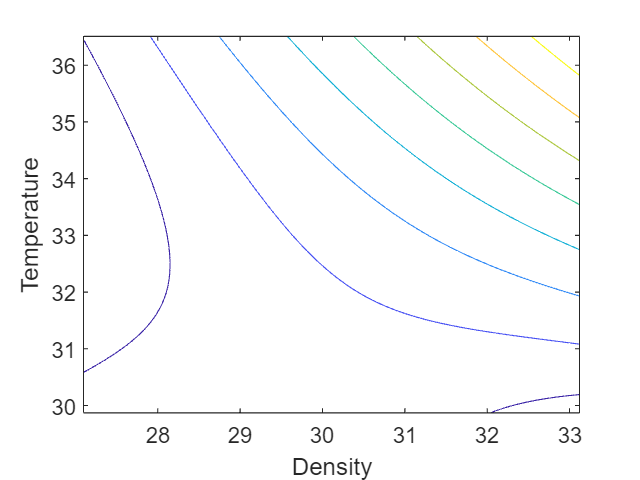


contour(rlist, Tlist, d2pdr2_r)
xlabel("Density")
ylabel("Temperature")



% Find T, P, rho at numerical critical point